clc;
clear all;

M1 = 5;
M2 = 20;
K1 = 150;
K2 = 700;
B1 = 15;
B2 = 30;

A = [0 0 1 0; 0 0 0 1; (-K1/M1) (K1/M1) (-B1/M1) (B1/M1); (K1/M2) (-(K1+K2)/M2) (B1/M2) (-(B1+B2)/M2)];
B = [0;  0; 1/M1; 0];
C = [1 0 0 0];
D = 0;
x0 = [0.1; 0; 0; 0];

sys = ss(A,B,C,D)

sys =
 
  A = 
          x1     x2     x3     x4
   x1      0      0      1      0
   x2      0      0      0      1
   x3    -30     30     -3      3
   x4    7.5  -42.5   0.75  -2.25
 
  B = 
        u1
   x1    0
   x2    0
   x3  0.2
   x4    0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



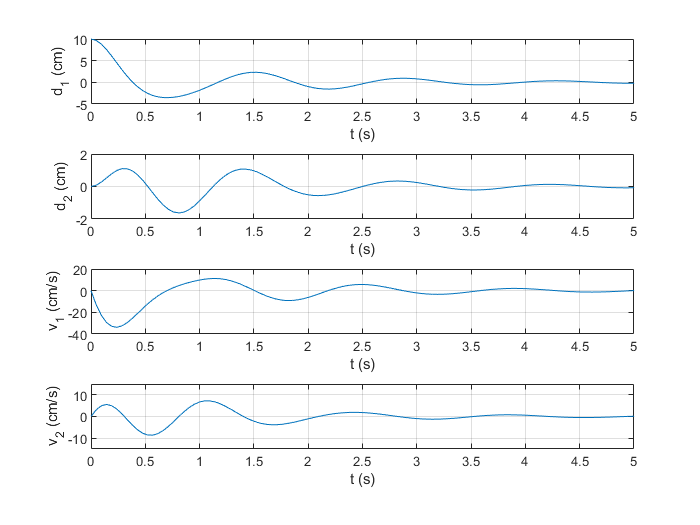


[y,t,x] = initial(sys,x0);

subplot(4,1,1)
plot(t,100*y)
xlabel('t (s)')
ylabel('d_1 (cm)')
grid
axis([0 5 -5 10])

subplot(4,1,2)
plot(t,100*x(:,2))
xlabel('t (s)')
ylabel('d_2 (cm)')
grid
axis([0 5 -2 2])

subplot(4,1,3)
plot(t,100*x(:,3))
xlabel('t (s)')
ylabel('v_1 (cm/s)')
grid
axis([0 5 -40 20])

subplot(4,1,4)
plot(t,100*x(:,4))
xlabel('t (s)')
ylabel('v_2 (cm/s)')
grid
axis([0 5 -15 15])


[H,s] = ss2tf(A,B,C,D)

H =          0         0    0.2000    0.4500    8.5000


s = 	1.0e+03 *

    0.0010    0.0053    0.0770    0.1500    1.0500


Eqs = ss(A,B,C,D)

Eqs =
 
  A = 
          x1     x2     x3     x4
   x1      0      0      1      0
   x2      0      0      0      1
   x3    -30     30     -3      3
   x4    7.5  -42.5   0.75  -2.25
 
  B = 
        u1
   x1    0
   x2    0
   x3  0.2
   x4    0
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.

